## Part 1: SIFT Feature Detection

% Read in image and convert to grayscale
I1 = rgb2gray(imread('file1.png'));
I2 = rgb2gray(imread('file2.png'));

% Get SIFT features
p1_1 = detectSIFTFeatures(I1,"NumLayersInOctave",1,"Sigma",1.6);
p1_5 = detectSIFTFeatures(I1,"NumLayersInOctave",5,"Sigma",1.6);

% 1-layer octave
imshow(I1);
hold on;
plot(p1_1.selectStrongest(10),ShowScale=true);
title('SIFT with 1 Octave Layers');
octave_1_locs = sortrows(p1_1.selectStrongest(10).Location)

octave_1_locs = 10×2 single matrix
  190.6402  285.5652
  206.1346  161.0153
  225.4159   92.5776
  230.5446  380.5461
  295.7710  191.3200
  297.9984  193.7405
  405.1594  260.1191
  437.3518  237.7638
  464.7281  359.2389
  465.6700   25.3807


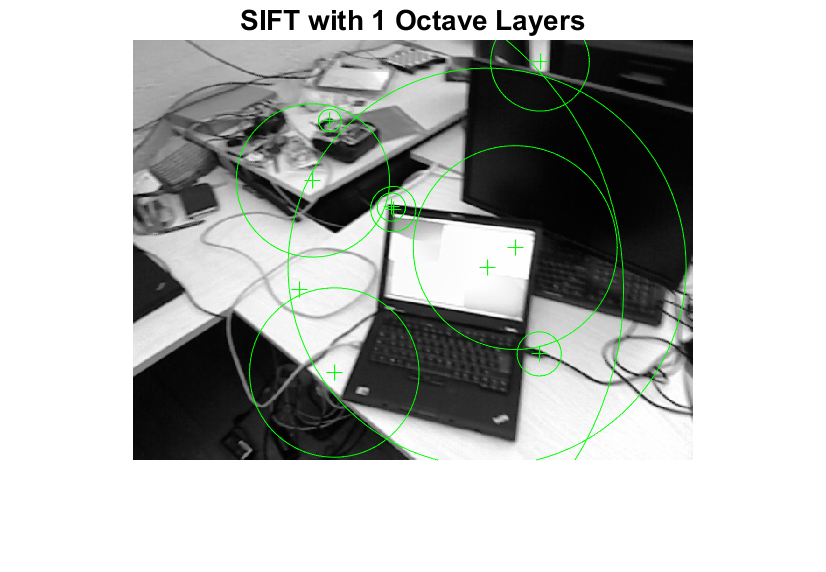

hold off;

% 5-layer octave
imshow(I1);
hold on;
plot(p1_5.selectStrongest(10),ShowScale=true);
title('SIFT with 5 Octave Layers');
octave_5_locs = sortrows(p1_5.selectStrongest(10).Location)

octave_5_locs = 10×2 single matrix
  230.5039  383.3771
  233.2014  194.7090
  298.0283  193.7501
  309.6738  146.5150
  396.4065  259.5421
  438.4415  236.7216
  464.4391  359.2346
  465.5540   24.6599
  592.0217  414.9056
  618.3234  415.4509


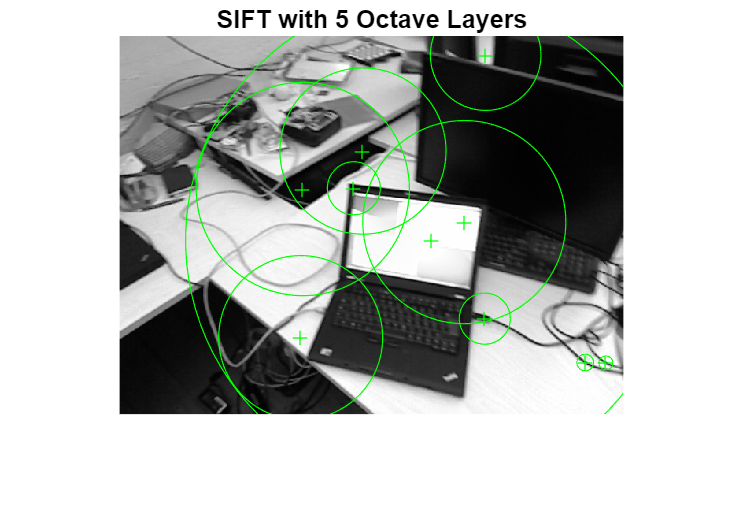

hold off;

With 1 layer per octave, there are 2 duplicating features at the top left of the laptop screen. Looking further, few features are quite ambiguous, proving that the current setting is not able to detect all features with enough efficiency. This shows that the first octave is not good enough to blur out noise, making redundant features likely to appear at stronger metric due to small discontinuities not being cleared out completely.

Setting to 5 layers per octave, the features now have less redundancy. SIFT is now more confident and efficient in finding distinctive image regions that correctly reflects the features in the image rather than misidentifying any noises. This is shown through the top 10 features having more consistent strengths and have reasonable distances from each other. The only drawback is that this setting would take longer to run due to increasing operations.

## Part 2: SIFT Matching

% Get the features in 2 images first
p1 = detectSIFTFeatures(I1,"NumLayersInOctave",3,"Sigma",1.6);
p2 = detectSIFTFeatures(I2,"NumLayersInOctave",3,"Sigma",1.6);
[f1,pts1]=extractFeatures(I1,p1);
[f2,pts2]=extractFeatures(I2,p2);

% 2.a Match features by hand
fprintf('Manually matching SIFT points');

Manually matching SIFT points

% Normalizing
nf1 = normalize(f1,2,'norm');
nf2 = normalize(f2,2,'norm');
% Get point with closest Euclidean distance on each side to another
[~,idx_2to1] = pdist2(nf2,nf1,'euclidean',Smallest=1);
[~,idx_1to2] = pdist2(nf1,nf2,'euclidean',Smallest=1);
ip_manual = [];
for i = 1:length(idx_2to1)
    % Ensure uniqueness by checking 1-to-1 relationship
    if idx_1to2(idx_2to1(i))==i
        ip_manual = [ip_manual; i idx_2to1(i)];
    end
end
ip_manual

ip_manual =      9    98
    10    99
    12   636
    14   538
    15   107
    16   108
    17   387
    18    23
    20    96
    22   101


% 2.b Match features using MATLAB function
fprintf('Use built-in function for matching SIFT points');

Use built-in function for matching SIFT points

% Matching by hand gets the same result as MATLAB function
ip = matchFeatures(f1,f2,MatchThreshold=100,MaxRatio=1.0,Unique=true)

ip = 318×2 uint32 matrix
     9    98
    10    99
    12   636
    14   538
    15   107
    16   108
    17   387
    18    23
    20    96
    22   101


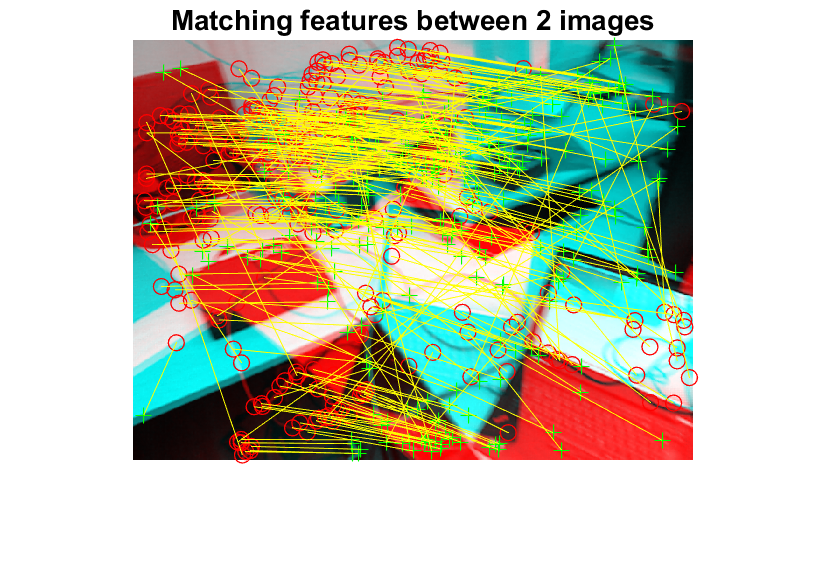

ip1 = ip(:,1);
ip2 = ip(:,2);
figure; 
showMatchedFeatures(I1,I2,pts1.Location(ip1,:),pts2.Location(ip2,:));
title('Matching features between 2 images');

% The feature matching seems to work well, with the majority of matching pairs reflecting the correct transformation.

## Part 3: Homography Matrix

% Setting up camera parameters
f = [517.3,516.5];
oc = [318.6, 255.3];
cam_info = cameraIntrinsics(f,oc,size(I1));

% Random seed for consistent result
rng(1025294);
% We see that 2 sides of the laptop keyboard are not parallel in the image. Therefore, the transformation would be projective
% Also, ensure that the function converges by increasing iteration limit
h = estimateGeometricTransform2D(pts1(ip1,:),pts2(ip2,:),"projective",MaxNumTrials=1500);
homography_matrix = h.T

homography_matrix = 3×3 single matrix
    0.7019    0.0458   -0.0005
   -0.1703    0.8892   -0.0001
  223.6992   11.5741    1.0000


% Get the camera transformation
[orientation,location] = relativeCameraPose(h,cam_info,pts1(ip1,:),pts2(ip2,:))

orientation = 3×3 single matrix
    0.9345   -0.1577    0.3191
    0.1186    0.9832    0.1385
   -0.3356   -0.0915    0.9376


location = 1×3 single row vector
    0.0670    0.6788    0.7312
